## Actividad 2

    Se busca la curva que genera la superficie de revolución más pequeña alrededor del eje horizontal. Para ello, se aproxima la integral que proporciona la superficie por una expresión algebraica empleando el método de los trapecios. Luego, se resuelve el problema de optimización sobre esta última aproximación mediante el método del descenso del gradiente. 

    Se comienza definiendo el número de nodos de integración 'n' para el método de los trapecios y construyendo la expresión para la función objetivo que aproxima la integral.

% Parámetros
n = 100; % Nodos de integración
maxiter = 1e5; % Número máximo de iteraciones
eps = 1e-6; % Precisión/Tolerancia

% Implementación del algoritmo del descenso del gradiente
k = 0; % Número de iteraciones
u = ones(1,n-1); % Inicialización arbitraria de los nodos de integración
grad = Gradiente(n,u); % Construcción del gradiente
norma = sqrt(grad'*grad);

while norma > eps && k < maxiter
    k = k + 1;

    % Función anónima de una sola variable
    g = @(t)FuncionObjetivo(n,u-t*grad');

    % Se resuelve el problema de optimización unidimensional empleando el
    % método de búsqueda de la sección áurea.
    [t_opt,~,~] = SeccionAurea(g,1e-6,0,0.1);

    u = u-t_opt*grad';
    grad = Gradiente(n,u);
    norma = sqrt(grad'*grad);
end

disp(u);

   0.993828422219680   0.987794936206046   0.981898703534508   0.976138904855530   0.970514739780632   0.965025426771048   0.959670203028991   0.954448324391530   0.949359065227063   0.944401718334361   0.939575594844173   0.934880024123392   0.930314353681752   0.925877949081042   0.921570193846846   0.917390489382774   0.913338254887176   0.909412927272343   0.905613961086164   0.901940828436242   0.898393018916451   0.894970039535923   0.891671414650469   0.888496685896398   0.885445412126761   0.882517169349958   0.879711550670785   0.877028166233777   0.874466643169056   0.872026625540324   0.869707774295559   0.867509767219510   0.865432298889411   0.863475080631656   0.861637840482906   0.859920323150391   0.858322289979083   0.856843518914715   0.855483804478095   0.854242957729521   0.853120806251708   0.852117194113965   0.851231981865376   0.850465046497139   0.849816281447379   0.849285596560598   0.848872918104638   0.848578188727358   0.848401367484880   0.848342429797100

% Función objetivo evaluada en el punto óptimo (aproximación de la superficie de revolución)
T = FuncionObjetivo(n,u);
disp(T);

   0.953629018242541



#### Curva teórica

La solución del problema es $u(x)=a\cosh{\Bigl(\frac{x-b}{a}\Bigr)}$. Las constantes se determinan imponiendo $u(0)=u(1)=1$. Resulta inmediato comprobar que $b=0.5$ por paridad del coseno hiperbólico. Para la constante $a$ se usa el método de Newton-Rapshon:

f = @(a)a*cosh(0.5/a)-1;
[a,~] = NewtonRaphson(f,1e-10,0.7)

a =    0.848337938094979


La solución exacta es $u(x)=0.84833\cosh{\Bigl(\frac{x-0.5}{0.84833}\Bigr)}$. Representamos la curva exacta junto a la solución numérica.

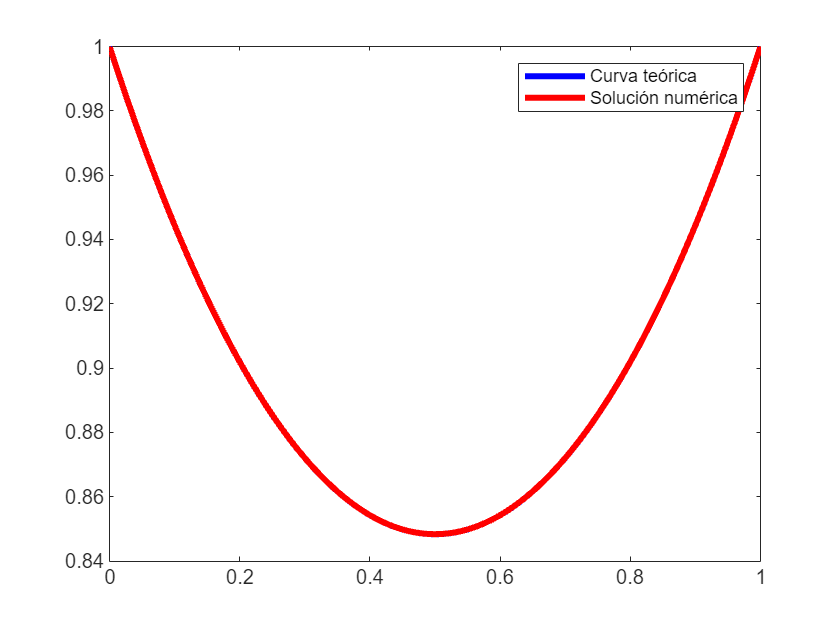

sol = ones(1,n+1);
sol(1,1) = 1;
sol(1,2:n) = u;
sol(1,n+1) = 1;
x = 0:1/n:1;
x_teo = linspace(0,1,1000);
y_teo = a*cosh((x_teo-0.5)/a);
plot(x_teo,y_teo,'b','LineWidth',3)
hold on
plot(x,sol,'r','LineWidth',3)
legend('Curva teórica', 'Solución numérica')

## Funciones empleadas

#### Construcción de la función objetivo

function T=FuncionObjetivo(n,u)
    T = 0;
    T = T + ((abs(u(1))+1)*sqrt(1+n^2*(abs(u(1))-1)^2))/(2*n); % Se fija u_0=1
    for i=1:n-2
        T = T + ((abs(u(i+1))+abs(u(i)))*sqrt(1+n^2*(abs(u(i+1))-abs(u(i)))^2))/(2*n);
    end
    T = T + ((1+abs(u(n-1)))*sqrt(1+n^2*(1-abs(u(n-1)))^2))/(2*n); % Se fija u_n=1
end

#### Construcción del gradiente de la función objetivo  

function grad=Gradiente(n,u)
    grad = zeros(n-1,1);
    grad(1,1) = ((n^2*(abs(u(1))-1)*(1+abs(u(1))))/sqrt(1+n^2*(abs(u(1))-1)^2)+...
            sqrt(1+n^2*(abs(u(1))-1)^2)+sqrt(1+n^2*(abs(u(2))-abs(u(1)))^2)-(n^2*(abs(u(2))-abs(u(1)))*(abs(u(1))+abs(u(2))))/...
            sqrt(1+n^2*(abs(u(2))-abs(u(1)))^2))/(2*n)*sign(u(1)); % Se fija u_0=1
    for i=2:n-2
        grad(i,1) = ((n^2*(abs(u(i))-abs(u(i-1)))*(abs(u(i-1))+abs(u(i))))/sqrt(1+n^2*(abs(u(i))-abs(u(i-1)))^2)+...
            sqrt(1+n^2*(abs(u(i))-abs(u(i-1)))^2)+sqrt(1+n^2*(abs(u(i+1))-abs(u(i)))^2)-(n^2*(abs(u(i+1))-abs(u(i)))*(abs(u(i))+abs(u(i+1))))/...
            sqrt(1+n^2*(abs(u(i+1))-abs(u(i)))^2))/(2*n)*sign(u(i));
    end
    grad(n-1,1) = ((n^2*(abs(u(n-1))-abs(u(n-2)))*(abs(u(n-2))+abs(u(n-1))))/sqrt(1+n^2*(abs(u(n-1))-abs(u(n-2)))^2)+...
            sqrt(1+n^2*(abs(u(n-1))-abs(u(n-2)))^2)+sqrt(1+n^2*(1-abs(u(n-1)))^2)-(n^2*(1-abs(u(n-1)))*(abs(u(n-1))+1))/...
            sqrt(1+n^2*(1-abs(u(n-1)))^2))/(2*n)*sign(u(n-1)); % Se fija u_n=1
end

#### Método de búsqueda de la sección áurea

function [centro,k,min]=SeccionAurea(f,h,x1,x2)
    % Función que halla el mínimo de una función unimodal implementando
    % el método de la sección áurea. Los parámetros son la función objetivo
    % 'f' introducida como función anónima, la tolerancia 'h' del método
    % y el intervalo [x1,x2] inicial. Se devuelve el intervalo final [a,b]
    % de acuerdo con la tolerancia, el número de iteraciones 'k' y el 
    % mínimo óptimo encontrado.

    % Número áureo menos uno
    r = (sqrt(5)-1)/2;

    % Paso inicial del método
    a = x1;
    b = x2;
    y = a + (1-r)*(b-a);
    z = a + r*(b-a);
    k = 0;
    f1 = f(y);
    f2 = f(z);

    % Implementación del método (100 es el máximo número de iteraciones)
    while b-a > h && k < 100

        if f1>=f2
            a = y;
            y = z;
            z = a + r*(b-a);
            f1 = f2;
            f2 = f(z);
        else
            b = z;
            z = y;
            y = a + (1-r)*(b-a);
            f2 = f1;
            f1 = f(y);
        end

        k = k + 1;

    end

    centro = (a+b)/2;
    min = f(centro);

end

#### Método de Newton-Raphson

function [x,k]=NewtonRaphson(f,h,x0)
% Función que implementa el método iterativo de Newton-Raphson para
% calcular el cero simple de una función continuamente diferenciable en un
% entorno de este. Toma por argumentos la función objetivo 'f' como función
% anónima, la tolerancia 'h' con la que se encuentra la solución y el punto
% inicial 'x0' por el que se comienza a buscar. La función devuelve la
% aproximación del valor donde ocurre el cero, 'x', y el número de
% iteraciones empleadas 'k'.

x = x0;
k = 1;

% Se crea una variable auxiliar simbólica, 'y', para calcular la derivada
% de la función 'f'.
syms y
g(y) = f(y);
dev_f = diff(g,y,1);

% Proceso iterativo
while abs(f(x)) > h && k < 100
    x = x - f(x)/double(dev_f(x));
    k = k + 1;
end

end